clear
close all

N_Sensors = 400;                % number of sensors in each trial
N_Trials = 10000;               % number of trials
range = [50 56];                % range of measured pollution level 
hist_range = [50:.1:56];        % range of histogram plot

%Note: Score stores an array of 100 variables during 1 loop iteration, it
%does this 1000 times
for iloop = 1:N_Trials
    score = randi(range, N_Sensors, 1);
    score_ave(iloop) = sum(score)/N_Sensors;
end

%Verifying the results of Part II experimentally P[Mn>=53.2]
P_Mn=sum(score_ave>53.2 & score_ave<56)/N_Trials

P_Mn = 0.0228

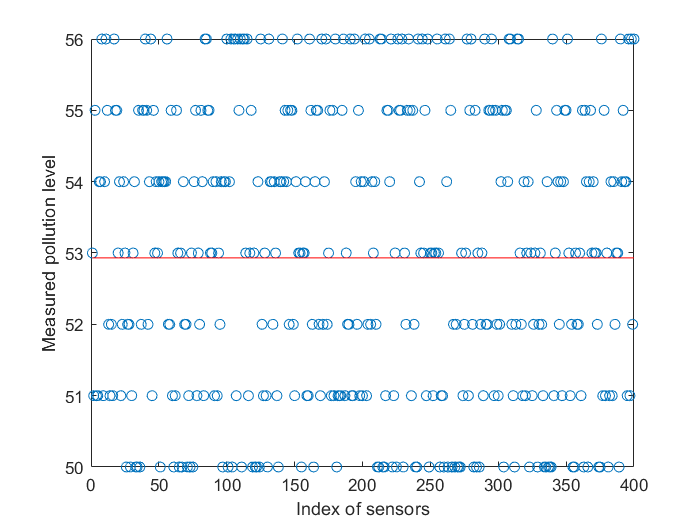

hist_result = hist(score_ave, hist_range);

%Plotting results
figure(1)
plot(score,'o')
hold on
plot(score_ave(end)*ones(N_Sensors,1),'r');
xlabel('Index of sensors'); ylabel('Measured pollution level')

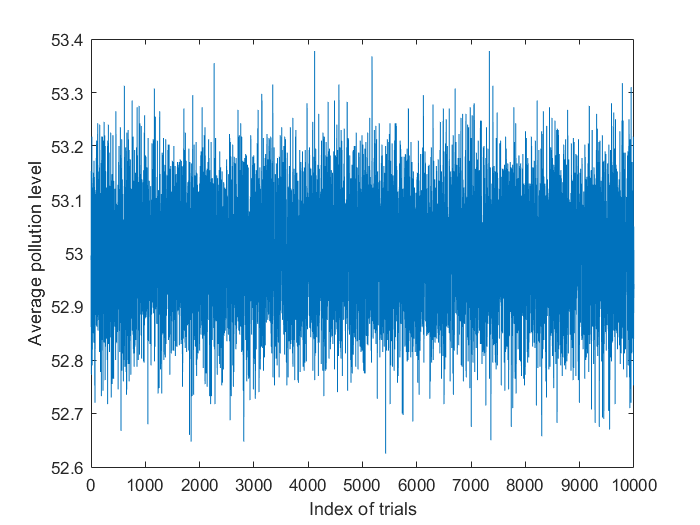


figure(2)
plot(score_ave)
xlabel('Index of trials');ylabel('Average pollution level')

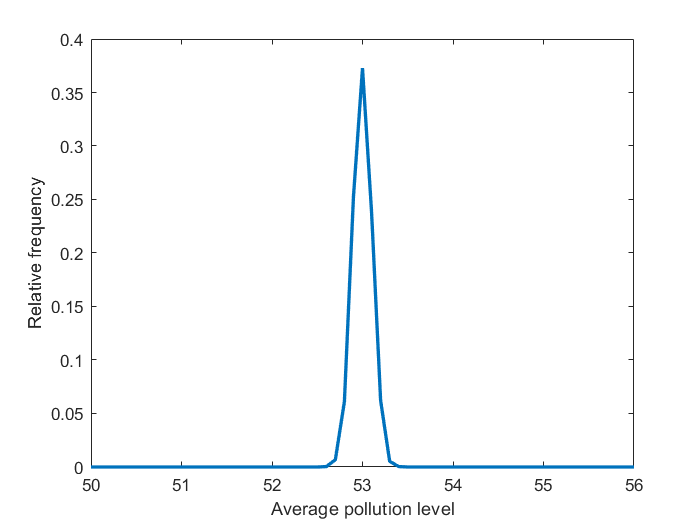


figure(3)
plot(hist_range, hist_result/N_Trials,'-','LineWidth',2)
xlim(range)
xlabel('Average pollution level'); ylabel('Relative frequency')